# **基于机器学习的ECG分类模型**

### 研究背景与意义

心血管疾病已成为目前全球非传染性疾病的主要死因，每年死于心血管疾病的人数高于任何其他死因。由于高患病率与高死亡率，心血管疾病给人们不断的带来越来越重的负担，其逐渐成为研究的热点课题。心律失常是一种常见的心血管综合征，心脏电刺激的起源位置异常、传导顺序异常和频率改变均会造成心律失常，是目前临床心血管疾病治疗所面临的重大难题。

目前广泛应用于心律失常检测的方法是心电图（Electrocardiogram，ECG）诊断。心律失常是一种极其常见而又非常重要的心电活动异常状态，不同的心律异常类型，在心电图波形以及心电图频率上会呈现出不同的状态，研究心电信号可以对多种心律失常症状进行诊断。采取有效措施检测心律失常的发生对心血管疾病的预防和诊断具有很大积极作用，具有十分重要的临床意义。

本程序主要分析处理正常心电及三种常见心律失常类型:

（1）正常搏动（Normal beat，**N**）

（2）左束支阻滞（Left bundle branch block beat，**L**）：左束支在心脏电激动传导过程中可能出现的传导异常中断。在心电图中主要特点是R波的宽峰出现顿挫，时限一般不小于0.11s。

（3）右束支阻滞（Left bundle branch block beat，**R**）：右心室壁在心脏电激动传导过程可能发生的阻滞异常。在心电图中的主要特点是QRS波形可能发生改变，如增宽、时限延长、粗顿等。

（4）室性早搏（Premature ventricular contraction，**V**）：心室在心脏电激动传导到心室之前可能提前发生激动异常。在心电图中的主要特点是提早出现QRS波群，且一般认为QRS波群范围变宽大。

数据来源于MIT-BIH Arrhythmia Database（[MIT-BIH Arrhythmia Database v1.0.0 (physionet.org)](https://physionet.org/content/mitdb/1.0.0/)，本程序都提取MLII导联方式测得的数据（通过将电极置于胸部而获得），即37条心电数据。

本示例使用长短期记忆 (LSTM) 网络，这是一种循环神经网络 (RNN)，非常适合研究序列和时间序列数据。LSTM 网络可以学习序列的时间步之间的长期相关性。LSTM 层 ([`lstmLayer`](https://127.0.0.1:31515/static/help/deeplearning/ref/nnet.cnn.layer.lstmlayer.html) (Deep Learning Toolbox)) 可以前向分析时间序列，而双向 LSTM 层 ([`bilstmLayer`](https://127.0.0.1:31515/static/help/deeplearning/ref/nnet.cnn.layer.bilstmlayer.html) (Deep Learning Toolbox)) 可以前向和后向分析时间序列。此程序使用单向 LSTM 层。

## 一、用wfdb库导入所需数据

首先，使用MATLAB的函数`fopen`打开'`database\mitdb\RECORDS.txt'`文件，该文件包含心电图记录的文件名。然后，使用MATLAB的函数`textscan`将文件中的文本读取到一个字符串数组`data`中。接下来，使用`fclose`函数关闭文件。

然后，将文件名存储到一个数组`file_names`中，使用`cell`函数创建一个元胞数组`data_original`，其大小为`37x1`（假设有37个文件名在`RECORDS.txt`文件中）。

接下来，使用一个循环，将每个文件名读取到`rdsamp`函数中。该函数读取一个MIT-BIH记录文件，然后返回一个包含信号数据、采样率（Fs）和时间轴（tm）的数据结构。使用这些数据，将每个信号存储到`data_original`数组中。

最后，使用MATLAB的`save`函数将`data_original`数组存储到一个MATLAB文件`data_original.mat`中，以便以后可以在MATLAB中使用这些数据进行分析和处理。

clear,clc,close all;

addpath 'C:\Users\Du\Documents\MATLAB\Examples\R2022b\data_download\mcode'
fileID = fopen('database\mitdb\RECORDS.txt','r');% 打开文件
data = textscan(fileID, '%s');% 读取数据
fclose(fileID);% 关闭文件
file_names = data{1};% 将数据存储到数组中
data_original = cell(length(file_names), 1);% 创建一个37x1的空元胞数组

% 读取数据
for i = 1:length(file_names)
    [signal, Fs, tm] = rdsamp(['database\mitdb\', file_names{i}], 1);
    data_original{i} = signal;
end

error executing: wfdb-config
java.io.IOException: Cannot run program "C:\Users\Du\Documents\MATLAB\Examples\R2022b\data_download\mcode\nativelibs\windows\bin\wfdb-config": CreateProcess error=2, 系统找不到指定的文件。
	at java.lang.ProcessBuilder.start(ProcessBuilder.java:1048)
	at org.physionet.wfdb.Wfdbexec.execToStringList(Unknown Source)
	at org.physionet.wfdb.Wfdbexec.execToStringList(Unknown Source)
Caused by: java.io.IOException: CreateProcess error=2, 系统找不到指定的文件。
	at java.lang.ProcessImpl.create(Native Method)
	at java.lang.ProcessImpl.<init>(ProcessImpl.java:386)
	at java.lang.ProcessImpl.start(ProcessImpl.java:137)
	at java.lang.ProcessBuilder.start(ProcessBuilder.java:1029)
	... 2 more


错误使用 javaObject
未在 Java 类路径中找到类 org.physionet.wfdb.jni.Rdsamp

出错 rdsamp (第 114 行)
    javaWfdbRdsamp=javaObject('org.physionet.wfdb.jni.Rdsamp');

save('data_original.mat', 'data_original');

## 二、将提取到的心电数据进行小波阈值去噪

在对心电信号进行分析前，需要对其进行去噪预处理。因为在心电信号采集或者数模转换的过程中，会产生噪声，包括工频干扰、肌电干扰、基线漂移这三种。本程序将介绍目前十分常用且有效的一种去噪方法——小波阈值去噪。

对读取的MIT-BIH心电数据进行小波变换降噪，并将结果保存到一个名为`data_denoised.mat`的MATLAB文件中。代码中使用了Birge-Massart策略和硬阈值来降噪。

首先，使用`addpath`函数添加小波变换的MATLAB代码路径。然后，如果当前工作区中不存在名为`data_original`的变量，则使用`load`函数从`data_original.mat`文件中加载数据。

然后，使用一个循环，对每个心电信号进行小波变换。**使用小波函数**`wavedec`**将信号进行小波分解，使用' db5'小波基函数和4级小波分解。然后，使用Birge-Massart策略计算出阈值，并使用硬阈值将信号降噪，**将结果存储在`data_denoised`数组中。

最后，绘制原始心电信号和降噪后的信号的图形。使用MATLAB的`subplot`函数将它们显示在同一张图上。

**信噪比SNR越大，均方差值MSE越小，说明去噪效果越好。**

Birge_Massart;

## 三、提取人工注释信息划分心拍

**ANNOT：存储了该记录中各心拍的人工标注类型。**ANNOT文件中的数字，分别代表了当时人工标注的心脏的情况它提供给了我们各心拍专家诊断的结果，用于后续深度学习算法的标签。

**ATRTIME：存储了各心拍的人工标注位置。**即它记录了数据中几分几秒出现了一个心拍。而这个矩阵的意义在于后续帮助我们评估心拍定位算法的准确性，或是直接根据它提供的人工标注位置截取心拍。

遍历 file_names 中的每个文件，对于每个文件，遍历标签为 N、L、R、V 的注释类型，如果注释的位置在数据范围内，则将**以注释为中心的前后 150 个点的数据**存储到相应的样本数组 SAMPLE_N、SAMPLE_L、SAMPLE_R、SAMPLE_V 中，并将样本计数器 count_N、count_L、count_R、count_V 分别加一。

绘制第一个样本的波形图，分别绘制 SAMPLE_N{1}、SAMPLE_L{1}、SAMPLE_R{1}、SAMPLE_V{1} 中的一个。绘制的波形图横坐标为时间轴，纵坐标为电压值。

beat_division;

## 四、提取心电信号时域特征

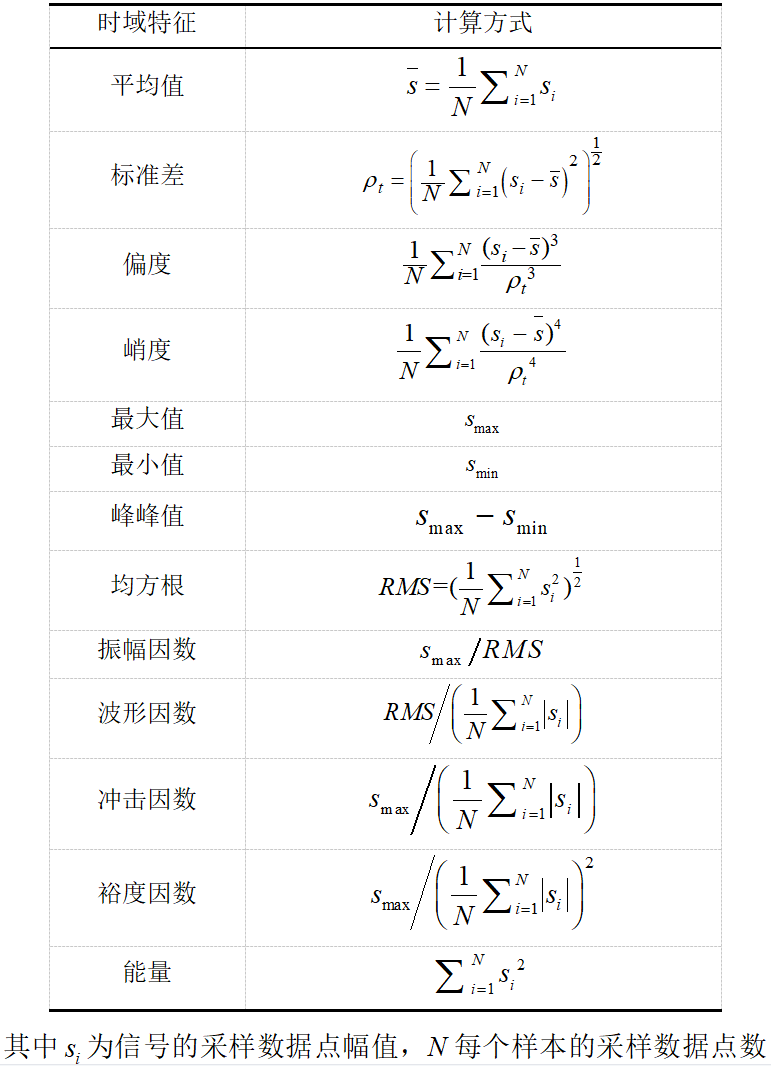

由于约 N样本信号的比例过大，因此分类器会发现通过简单地将所有信号分类为正常信号就可达到高准确度。为了避免这种偏置，可以通过复制数据集中的 L,R,V 信号来增加数据，以便N信号和 L,R,V 信号的数量相同。这种复制通常称为上采样（也叫过采样），是深度学习中使用的一种数据增强形式。

此外还可以通过减少N样本的数量，同样达到N信号和 L,R,V 信号的数量相同的效果。这种减少多数样本数量通常称为下采样。

因考虑到运行时间和电脑内存限制，**本程序采用下采样的方式，将L,N,R,V样本数量都控制在5000**。

features_extract;

## 五、使用LSTM长短期记忆网络对ECG信号进行分类

LSTM 网络可以学习序列数据的时间步之间的长期相关性。此程序使用双向 LSTM 层 `lstmLayer。`

%%  导入数据
res = xlsread('数据集(时域特征).xlsx');

将数据集划分为训练集和测试集，并且比例为0.9：0.1，即训练数据18000条，测试数据2000条。

%%  划分训练集和测试集
temp = randperm(20000);

P_train = res(temp(1: 18000), 1: 13)';
T_train = res(temp(1: 18000), 14)';
M = size(P_train, 2);

P_test = res(temp(18001: end), 1: 13)';
T_test = res(temp(18001: end), 14)';
N = size(P_test, 2);

数据归一化是一种数据预处理技术，它的目的是将数据调整到相同的比例范围内，以消除不同特征之间的量纲影响。

- **消除量纲影响：**不同特征可能有不同的度量单位，比如体重和身高，一个是以千克为单位，另一个是以厘米为单位。因此，如果不对数据进行归一化，那么不同特征之间的比较将变得困难。

- **提高模型效果：**在使用许多机器学习算法时，例如支持向量机（SVM）和k-近邻算法（KNN），它们通常都是基于距离计算的。如果数据没有进行归一化，那么可能会导致一个特征对距离计算的影响远大于另一个特征。这将导致算法错误地给出较高的权重或重要性。

- **加速训练速度**：训练机器学习模型需要大量计算，而归一化可以缩小数据范围，从而加速计算速度。

本程序采用最大最小归一化，标准化是一个线性变换，**使得变换后的数据均值为0，方差为1**，通过标准化操作，我们就能确定算法不会受特征尺度的影响。

%%  数据归一化
[P_train, ps_input] = mapminmax(P_train, 0, 1);
P_test = mapminmax('apply', P_test, ps_input);

t_train = categorical(T_train)';
t_test  = categorical(T_test )';

%%  数据平铺
%   将数据平铺成1维数据只是一种处理方式
%   也可以平铺成2维数据，以及3维数据，需要修改对应模型结构
%   但是应该始终和输入层数据结构保持一致
P_train =  double(reshape(P_train, 13, 1, 1, M));
P_test  =  double(reshape(P_test , 13, 1, 1, N));

%%  数据格式转换
for i = 1 : M
    p_train{i, 1} = P_train(:, :, 1, i);
end

for i = 1 : N
    p_test{i, 1} = P_test( :, :, 1, i);
end

创建了一个由多个层组成的神经网络。网络的第一层是一个 sequenceInputLayer，用于将输入数据转换为序列数据。接下来是一个 LSTM 层，它有6个隐层节点，输出模式为 "last"，表示只输出序列的最后一个时间步。之后是一个 Relu 激活层，用于增强网络的非线性能力。然后是一个全连接层，包含4个输出节点，最后是一个 softmax 分类层和一个 classificationLayer，用于对输入序列进行分类。

%%  创建网络
layers = [ ...
  sequenceInputLayer(13)               % 输入层
  
  lstmLayer(6, 'OutputMode', 'last')   % LSTM层
  reluLayer                            % Relu激活层
  
  fullyConnectedLayer(4)               % 全连接层
  softmaxLayer                         % 分类层
  classificationLayer];

设置了训练模型时使用的参数。其中，

- `'``adam'` 表示使用 Adam 优化算法进行梯度下降；

- `'MiniBatchSize'         `表示每次迭代训练时使用的批量数据大小；

- `'MaxEpochs'             `表示最大迭代次数；

- `'InitialLearnRate'`            表示初始学习率；

- `'LearnRateSchedule'     `表示学习率调度方式；

- `'LearnRateDropFactor'`      表示学习率下降因子；

- `'LearnRateDropPeriod'   `表示学习率下降的周期；

- `'Shuffle'   `                        表示是否在每次迭代训练前打乱数据集；

- `'ValidationPatience' `      表示验证的耐心，即连续多少个迭代的验证误差没有降低就停止验证；

- `'Plots' `                                表示是否画出训练曲线；

- `'Verbose'   `                        表示是否在命令行窗口显示训练过程。由于其设置为 false，因此不会显示训练过程中的详细信息。

此程序使用自适应矩估计 (ADAM) 求解器。与默认的具有动量的随机梯度下降 (SGDM) 求解器相比，ADAM 在使用 LSTM 之类的 RNN 时性能更好。

%%  参数设置
options = trainingOptions('adam', ...       % Adam 梯度下降算法
    'MiniBatchSize', 100, ...               % 批大小
    'MaxEpochs', 1000, ...                  % 最大迭代次数
    'InitialLearnRate', 1e-2, ...           % 初始学习率
    'LearnRateSchedule', 'piecewise', ...   % 学习率下降
    'LearnRateDropFactor', 0.1, ...         % 学习率下降因子
    'LearnRateDropPeriod', 700, ...         % 经过700次训练后 学习率为 0.01 * 0.1
    'Shuffle', 'every-epoch', ...           % 每次训练打乱数据集
    'ValidationPatience', Inf, ...          % 关闭验证
    'Plots', 'training-progress', ...       % 画出曲线
    'Verbose', true);

通过使用 `trainNetwork` 用指定的训练选项和层架构训练 LSTM 网络。由于训练集很大，训练过程可能需要四五十分钟左右。

%%  训练模型
net = trainNetwork(p_train, t_train, layers, options);

训练进度图的顶部子图表示训练准确度，即基于每个小批量的分类准确度。当训练在成功进行时，此值通常会逐渐增大，直到 100%。底部子图显示训练损失，即基于每个小批量的交叉熵损失。当训练在成功进行时，该值通常会逐渐降低，直到为零。

如果训练未收敛，绘图可能会在各值之间振荡，而不会呈现向上或向下趋势。这种振荡意味着训练准确度没有提高，训练损失没有减少。这种情况可能发生在训练开始时，或者在训练准确度有初步提高后，绘图可能趋于平稳。在许多情况下，更改训练选项可以帮助网络实现收敛。**减少 **`MiniBatchSize`** 或减少 **`InitialLearnRate`** 可能会导致更长的训练时间，但这可能有助于网络更好地学习。**

查看LSTM网络结构

%%  查看网络结构
analyzeNetwork(net)

## 六、**可视化训练和测试准确度**

在机器学习领域，混淆矩阵（Confusion Matrix）是一种常见的评估模型性能的方式，通常用于评估分类问题中的模型性能。混淆矩阵是一个二维矩阵，其中每行表示真实类别，每列表示预测类别。对于二分类问题，混淆矩阵如下：

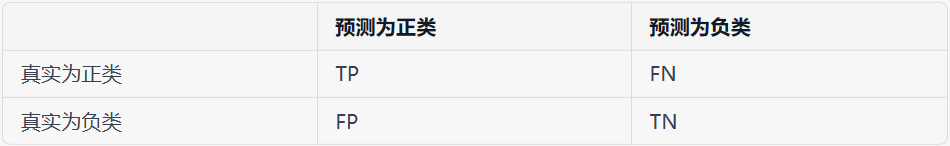

其中，TP表示真正例数（True Positive），即将正例预测为正例的数量；FN表示假反例数（False Negative），即将正例预测为负例的数量；FP表示假正例数（False Positive），即将负例预测为正例的数量；TN表示真反例数（True Negative），即将负例预测为负例的数量。

混淆矩阵能够直观地反映出分类模型的性能。通过混淆矩阵，可以计算出各种评估指标，例如精确度（Precision）、召回率（Recall）、F1值等。例如，对于二分类问题，精确度、召回率、F1值的计算公式如下：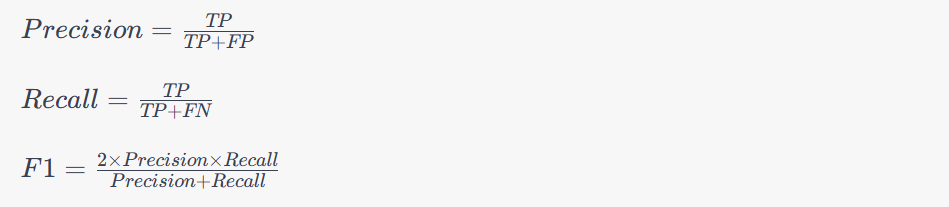

%%  仿真预测
t_sim1 = predict(net, p_train); 
t_sim2 = predict(net, p_test ); 

%%  数据反归一化
T_sim1 = vec2ind(t_sim1');
T_sim2 = vec2ind(t_sim2');

%%  性能评价
error1 = sum((T_sim1 == T_train)) / M * 100 ;
error2 = sum((T_sim2 == T_test )) / N * 100 ;

%%  数据排序
[T_train, index_1] = sort(T_train);
[T_test , index_2] = sort(T_test );

T_sim1 = T_sim1(index_1);
T_sim2 = T_sim2(index_2);

使用 confusionchart 函数绘制训练集的混淆矩阵。其中，T_train 是训练集真实标签，T_sim1 是训练集模型预测标签, T_test 是测试集真实标签，T_sim2 是测试集模型预测标签。混淆矩阵的行表示真实标签，列表示预测标签。

%%   绘制混淆矩阵
figure
cm = confusionchart(T_train, T_sim1);
cm.Title = 'Confusion Matrix for Train Data';
cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';
figure
cm = confusionchart(T_test, T_sim2);
cm.Title = 'Confusion Matrix for Test Data';
cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';

保存训练好的支持向量机模型，可以使用MATLAB内置的save函数将模型保存在本地磁盘上。

% 保存学习后的模型
save('net.mat', 'net');

% 查看网络结构
analyzeNetwork(net)

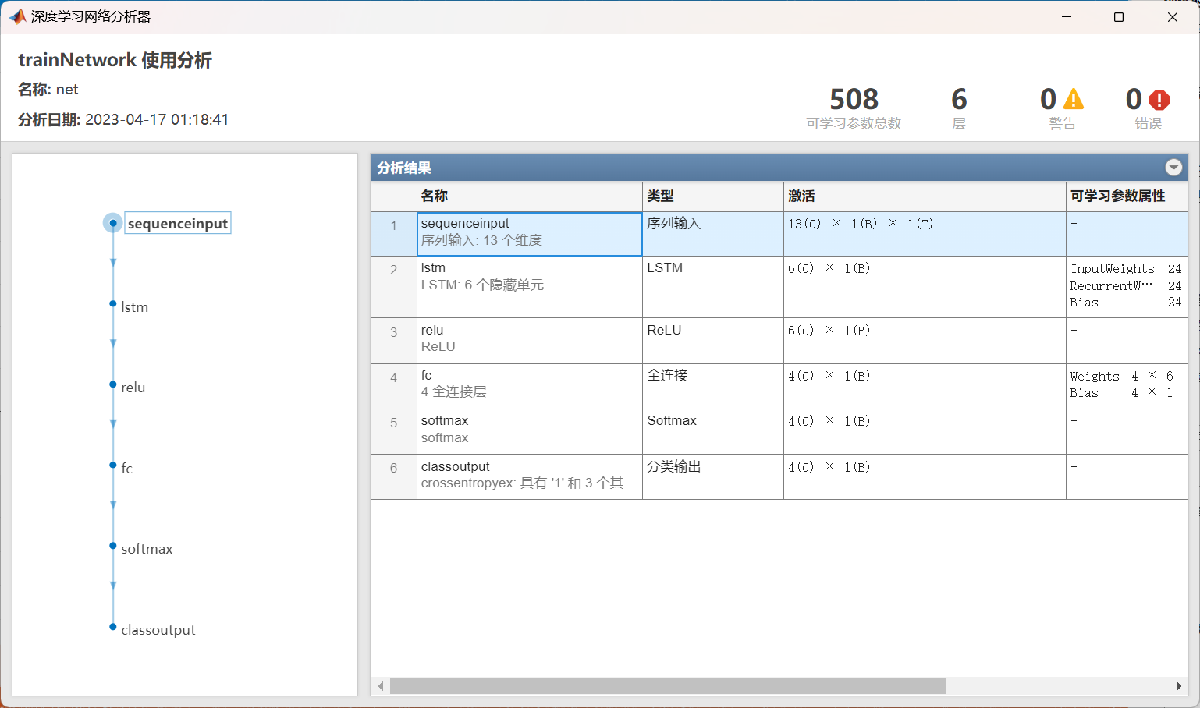

# **Pan-Tompkins法**

Pan-Tompkins法是一种用于心电图（ECG）信号处理中的心率检测算法，它可以检测出心电图中的QRS波群，即心脏电激动的主要特征之一。Pan-Tompkins法是一种基于波形形态的方法，通过分析QRS波群在ECG信号中的形态特征，来确定心率。

Pan-Tompkins法的主要思想是通过分析ECG信号的斜率、幅度和宽度等特征，来检测QRS波群的起始点和终止点。该算法包括以下主要步骤：

- 滤波：首先对原始ECG信号进行滤波，通常使用带通滤波器，以去除噪声和突发干扰。

- 导联选择：选择一个合适的导联，通常选择I导联，因为它在QRS波群的形态上最为明显。

- 特征提取：计算QRS波群在ECG信号中的斜率、幅度和宽度等特征。一般来说，QRS波群在ECG信号中的斜率较大、幅度较大且宽度较窄，这些特征可以用来检测QRS波群的起始点和终止点。

- 基线漂移校正：对QRS波群的斜率特征进行基线漂移校正，以消除ECG信号的基线漂移对QRS波群检测的影响。

- 积分：对校正后的QRS波群斜率特征进行积分，得到QRS波群的幅度特征。

- 移动平均：对QRS波群的幅度特征进行移动平均，以平滑幅度特征并降低噪声的影响。

- 判定阈值：根据移动平均后的幅度特征，确定QRS波群的判定阈值，用来检测QRS波群的起始点和终止点。

- 检测：根据判定阈值，检测QRS波群的起始点和终止点，从而得到心率信息。

Pan-Tompkins法在心电图信号处理中应用广泛，其优点是能够实时、准确地检测QRS波群，对噪声和基线漂移具有较强的抗干扰能力。但同时也存在一些局限性，例如对QRS波群形态的要求较高，对心律不齐和心率较快的情况可能不太适用。因此，虽然Pan-Tompkins法在许多情况下是一种有效的QRS波群检测算法，但在实际应用中，需要根据具体的临床场景和ECG信号特点来选择合适的算法和参数。同时，Pan-Tompkins法通常用于单导联的QRS波群检测，对于多导联的QRS波群检测，可能需要结合其他方法或者进行导联融合。

需要注意的是，作为一种心率检测算法，Pan-Tompkins法主要用于初步的QRS波群检测，可以用于计算心率和测量心律的基本参数。在实际临床应用中，还需要结合医生的临床判断和其他检查结果，以作出准确的诊断和治疗决策。

# **结论**

待完善。。。

# **后期设想**

**将支持向量机模型保存到STM32微控制器上，以便用该模型分类stm32采集到的心电数据，并通过上位机呈现采集到的心电波形以及分类结果。**

需要进行以下步骤：

- 将模型参数转换为可供STM32使用的格式：通常情况下，SVM模型是用MATLAB等高级编程语言训练的，并以某种形式保存。将模型参数转换为C语言格式是将模型移植到STM32所必需的。可以使用MATLAB的codegen功能将模型编译成可嵌入式平台使用的C代码，或者手动将模型参数导出为C语言头文件。

- 在STM32项目中添加模型代码：将模型代码添加到STM32项目中，通常是作为一个单独的源文件或库。

- 调用模型函数进行预测：在STM32代码中调用模型函数进行预测。通常，这涉及将输入数据作为函数参数传递给模型，然后读取模型的输出。

需要注意的是，将SVM模型移植到STM32上需要考虑到微控制器的内存、处理能力等限制。可能需要对模型进行优化或削减，以确保在STM32上能够快速、有效地执行。

# **参考资料**

[1] 葛丁飞，李时辉.基于ARMA模型的ECG分类和压缩[J].浙江科技学院学报，2004（01）：7-13.

[2] 毛雪岷，张婷婷，蔡传晰，李琼.基于ARMA模型的心电聚类算法[J].中国生物医学工程学报，2012，31（06）：816-821.

[3] 基于机器学习的心律失常分类(一)——基本理论介绍 - 知乎([https://zhuanlan.zhihu.com/p/144855071](https://zhuanlan.zhihu.com/p/144855071))

[4] MIT-BIH心律失常数据库详解_心跳脉搏数据库_海狸小生的博客-CSDN博客([https://blog.csdn.net/Mrm_cong/article/details/104668271](https://blog.csdn.net/Mrm_cong/article/details/104668271))